clear all
close all
clc



N = 1000;
p = 0.5;
c = 1;
L = 0.025;
r = 0.275;
numsteps = 200;



I0=10;
S0 = N - I0;
R0 = 0; 

F = @(S, I, R) [-p * c * S * I / N + L * R; p * c * S * I / N - r * I; r * I - L * R];

numRuns = 50;

figure('Position',[10,200,1600,800])

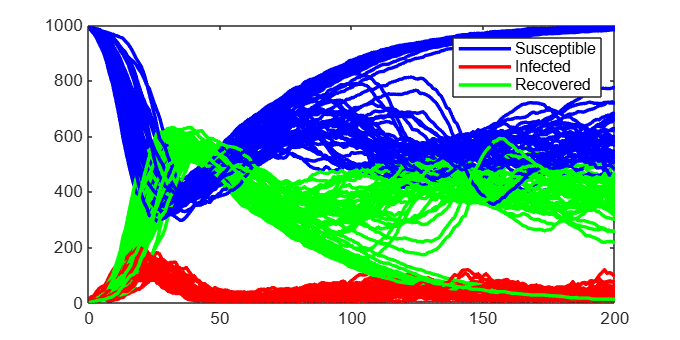

for run = 1:numRuns
    x(:, 1) = [S0; I0; R0];
    for k = 1:numsteps
        S = x(1, k);
        I = x(2, k);
        R = x(3, k);
        StoI = binornd(round(S), (p * c * I / N));
        ItoR = binornd(round(I), r);
        RtoS = binornd(round(R), L);

        x(:, k + 1) = x(:, k) + [-StoI + RtoS; StoI - ItoR; ItoR - RtoS];
    end
    plot(0:numsteps, x(1, :), 'b', 'MarkerSize', 10, 'LineWidth', 2)
    hold on
    plot(0:numsteps, x(2, :), 'r', 'MarkerSize', 10, 'LineWidth', 2)
    plot(0:numsteps, x(3, :), 'g', 'MarkerSize', 10, 'LineWidth', 2)
    legend('Susceptible', 'Infected', 'Recovered')
    pause(0.5)
end